## **Métodos ecuaciones no lineales**

**Ejemplo 1:**

f=@(x) exp(x)-2*x-1;
[x ,k] = biseccion(f, 1, 2, 1e-2, 10)

x =    1.257812500000000


k =      6


**Ejemplo 2:**

g=@(x) log(2*x+1);
[x , k] = puntofijo(g,2, 1e-2, 10)

x =    1.266278117855040


k =      7


Ejercicio **2.5**.4 (Adicionales)

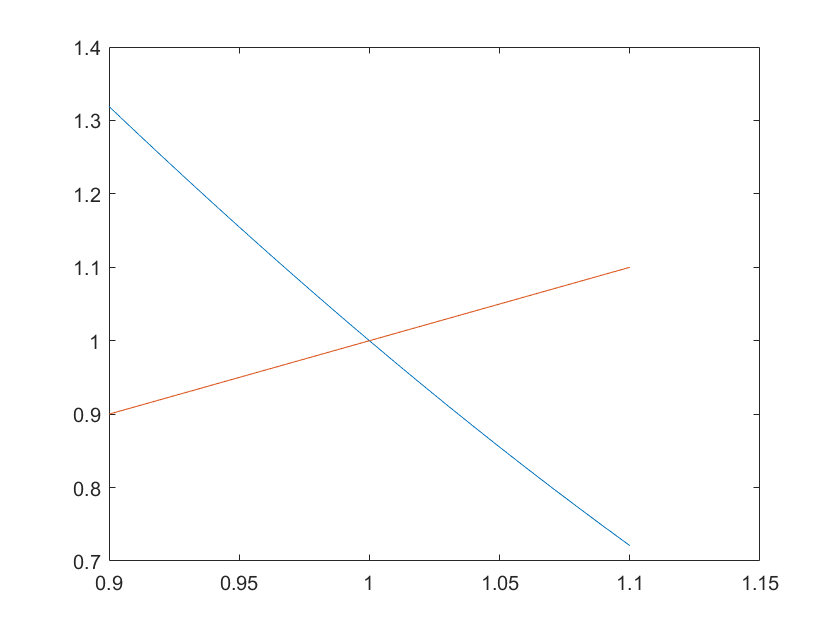

format;
x=0.9:0.01:1.1;    
y1=x.^3-x.^2-4*x+5;
y2=x;
plot(x,y1,x,y2)


% Usemos iteración de punto fijo para ver que la sucesión
% dará valores distantes de x=1
f=@(x) x.^3-x.^2-4*x+5;
[x , k] = puntofijo(f,0.9, 0.1, 10)

x = Inf

k = 9

## **Funciones**

**Script bisección dados tol e iterMax**

function [x ,k] = biseccion(f, a, b, tol, iterMax)
%Este método da una aproximación x al problema f(x)=0
%Inputs: f función, [a,b] intervalo, tol tolerancia
%iterMax iteraciones máximas
%Output: vector [x,k] donde x es la aproximación a la raíz
%k es la k+1 iteración (contando desde k=0)

% Verificar si se cumple la condición de cambio de signo
if f(a) * f(b) > 0
    disp('No se cumple el cambio de signo!')
    return %abandonar la función
end

if f(a)==0 || f(b)==0
    disp('Es un cero de f')
    return
end 
k = -1;
err = tol + 1;
while k < iterMax && err >= tol
    % Calcular x
    x = ( a + b ) / 2;
    % Determinar el valor de x y actualizar el intervalo
    if f(a) * f(x) <= 0
        b = x;
        else
            a = x;
    end
    % Preparar las siguiente iteración
    err = abs( b - a );
    k = k + 1;
end
end

**Script para método de bisección con criterio de parada **$|f(x_k)| \leq \text{tol}$** :**

function [c,k] = Biseccion1(f,a,b,tol)
%Este método da una aproximación c al problema f(x)=0
%Inputs: f función, [a,b] intervalo, tol tolerancia
%Output:[c,k,T] donde c es la aproximación a la raíz
% k son las iteraciones calculadas hasta que |f(c)|< tol
%T es una tabla =[iteración , a_k, b_k, c_k=(a_k+b_k)/2, f(c), abs(f(c))]

if f(a)*f(b)>0
    error('No se cumple el cambio de signo');
end
k=0;
c=(a+b)/2;
while abs(f(c))> tol
    if f(c)<0 && f(a)<0
        a=c;
    else
        b=c;
    end
    c=(a+b)/2;
    k=k+1;
 %   T(k,:) = [k a b c f(c) abs(f(c))];
    
end
end

**Script para método de bisección con criterio de parada iterMax dependiendo de tol:**

function [c,iterMax] = Biseccion2(f, a, b, tol)
%Este método da una aproximación c al problema f(x)=0
%Inputs: f función, [a,b] intervalo, tol tolerancia
%Output:[c, iterMax,T] donde c es la aproximación a la raíz
% iterMax son las iteraciones máximas calculadas teóricamente
%T es una tabla =[iteración , a_k, b_k, c_k=(a_k+b_k)/2, f(c), abs(b_k-a_k)] 


% Verificar si se cumple la condición de cambio de signo
if f(a)*f(b)>0
    error('No se cumple el cambio de signo');
end
k = 0;
err = tol + 1;
iterMax=ceil((log((b-a)/tol))/(log(2))-1);
while k < iterMax && err >= tol
    % Calcular c
    c = (a+b)/2;
    % Determinar el valor de c y actualizar el intervalo
    if f(a) * f(c) < 0
        b = c;
        else
            a = c;
    end
    % Preparar las siguiente iteración
    err = abs(b-a);
    k = k + 1;
%    T(k,:) = [k a b c f(c) err];
end
end

**Script para método de la secante:**

function [c, k] = secante(f, x0, x1, tol, iterMax )
    k = 0;
    err = tol+1;
    while k < iterMax && err >= tol 
        q = f(x1) - f(x0);
        if q==0 
            disp('Pendiente indefinida')
        end
         t = x1;
         x1 = x1-f(x1)*(x1-x0)/q;
         err = abs(x0-x1)/abs(x1);
         x0 = t;
         k = k+1;  
    end
    c = x1;

end

**Script Newton-Rhapson**

function [x,k] = NewRaph(f, df, x0, tol, iterMax )
k = 0;
x = x0;
err = tol+1;
    while k < iterMax && err >= tol 
        q = df(x);
            if q==0
                disp('Se anula la derivada')
            end
        x = x-f(x)/q;
        err = abs(x0-x)/abs(x);
        x0 = x;
        k = k+1;  
    end
end

**Script Punto Fijo**

function [x , k] = puntofijo(f,x0, tol, iterMax)
    k = 0;
    x = x0;
    err = tol+1;
    while k < iterMax && err > tol
        x = f(x);
        err = abs(x-x0)/abs(x);
        x0 = x;
        k = k+1;  
    end
end